clear
clc
clf
%Problem 3

M_a = linspace(0.1,4,100); %Mach number range - To find
T_o4 = 1778.15; %exit burner temperature (K)
delH = 43015.24; %Heating value of the fuel (j/kg)
mdotc = 65.7703; %core mass flow rate (kg/s)
P_atm = 4.11 * 10^4; %Atmospeheric pressure (Pa)
T_atm = 242.65; %Atmospheric temperature (K)
gamma = 1.4;
R = 287; %gas constant for air (j/kg.K)
cp = 1005; %Specific heat (j/kg.K)
a_a = sqrt(gamma * R * T_atm);% Speed of sound (m/s)
y = 1;
for x = linspace(0.1,4,100)
    u_a(1,y) = x.*a_a;
    T_oa(1,y) = T_atm * (1 + ((gamma - 1)/2)*(x).^2);
    T_o3 = T_oa;
    P_oa(1,y) = P_atm * ((1 + ((gamma - 1)/2).*(x).^2)).^(gamma/(gamma - 1)); % Total pressure at atm (Pa)
    P_o4 = P_oa;
    P_o3 = P_oa;
    P_o8 = P_oa;
    mdotf = ((mdotc * cp) * (T_o4 - T_oa))/(delH);
    f = mdotf/mdotc;
    T_o8 = T_o4;
    P_8 = P_atm;
    M_8 = sqrt((2/(gamma-1))*((P_o8/P_8).^((gamma-1)/(gamma)) - 1)); %exit mach
    T_8 = T_o8./(1 + (((gamma-1)/2) * (M_8).^2)); %(K)
    a_8 = sqrt(gamma * R .* T_8);
    u_8 = M_8 .* a_8;%(m/s)
    F = mdotc .* (u_8 - u_a);%Thrust (N)
    TSFC = mdotf./F; %(kg/s.N)
    tow_B = (u_8./u_a).^2;
    nonF = F./(mdotc * a_a); %Non-dimensional thrust
    y = y+1;
end

[min_tsfc, min_tsfc_index] = min(TSFC);
optimal_mach = M_a(min_tsfc_index)

optimal_mach = 3.4879

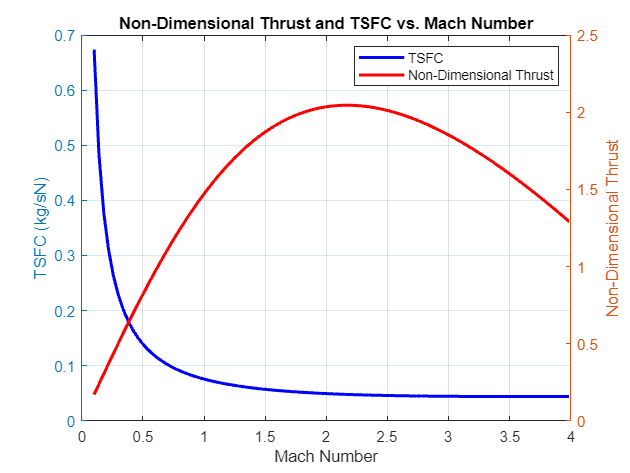

TSFC;
nonF;

yyaxis left;
plot(M_a, TSFC, 'b','LineWidth', 2);
xlabel('Mach Number');
ylabel('TSFC (kg/sN)');
title('Non-Dimensional Thrust and TSFC vs. Mach Number');

yyaxis right;
plot(M_a,nonF, 'r','LineWidth', 2);
ylabel('Non-Dimensional Thrust');
grid on
legend('TSFC', 'Non-Dimensional Thrust');